# Dynamics of a bubble on a smooth surface

## The Partial Differential Equations...

$\frac{\partial v_r}{\partial t} = \frac{F_R}{\rho} + \frac{2v_r^2}{r}$                                                                    (1)


$$\frac{\partial v_r}{\partial r} = - \frac{2v_r}{r}$$


$F_R = 2\pi (r - R_E) \gamma_{SL}$                                                            (2)

Combining these equations, we get


$$\frac{\partial r}{\partial t} = \frac{\partial r}{\partial v_r} \cdot \frac{\partial v_r}{\partial t} = - \frac{r}{2v_r} \left( \frac{2v_r^2}{r} + \frac{F_R}{\rho}\right) = -v_r-\frac{F_R r}{2v_r\rho}$$


$\frac{\partial r}{\partial t} = -v_r - \frac{\pi \gamma_{SL} r (r-R_E)}{v_r \rho}$                                                     (3)

Equations (1) and (3) have to be solved simultaneously.

Conservation of spherical cap volume gives us the following

$R_E^3(2+\cos{\theta_E})(1-\cos{\theta_E})^2 = r^3(2+\cos{\theta})(1-\cos{\theta})^2$     (4)

## Given data

clc; clear; close;
gamma_s = 1.614;                                % Surface tension - Stainless Steel, N/m
gamma_l = 0.072;                                % Surface tension - Water, N/m
theta_E = 71;                                   % Final Contact Angle, degrees
theta_io = 30;                                  % Initial Contact Angle, degrees
R_E = 2e-03;                                    % Final radius of water droplet, m
rho = 1000;                                     % Density, kg/m^3
gamma_sl = gamma_s - gamma_l * cosd(theta_E);   % Surface tension - Stainless Steel - Water, N/m
calc_lhs = R_E^3 * ( 2 + cosd(theta_E)) * (1 - cosd(theta_E))^2;

## Solution

v_r = 0.001;                                    % Initial Velocity, m/s
R_io = nthroot(calc_lhs /(( 2 + cosd(theta_io)) * (1 - cosd(theta_io))^2), 3); % Initial radius of water droplet, m
Final_v_r(1) = v_r;                             % Storing the velocity
Final_r(1)   = R_io;                            % Storing the radius of sphere
Final_t(1)   = 0;                               % Storing the time
Final_theta(1) = theta_io;                      % Storing the Contact Angle
i = 1;
while Final_r(i) > R_E                          % Radius should not exceed the final radius
    tspan = linspace(0,0.01,101);               % Time discretized till 0.01 secs

           
$$\frac{\partial v_r}{\partial t} =\frac{2v_r^2}{r} + \frac{2\pi (r - R_E) \gamma_{SL}}{\rho}$$


            
$$\frac{\partial r}{\partial t} = -v_r - \frac{\pi \gamma_{SL} r (r-R_E)}{v_r \rho}$$


    f = @(t,y) [2 * y(1)^2 / y(2) + (2 * pi * (y(2) - R_E) * gamma_sl) / rho; ...
                - y(1) - (pi * gamma_sl * y(2) * (y(2) - R_E)) / (y(1) * rho)];
    init = [Final_v_r(i), Final_r(i)];
    [t, yout] = ode45(f, tspan, init);          % Solution for System of Non Linear Differential Equations
    Final_v_r(i + 1) = yout(end,1);
    Final_r(i + 1)   = yout(end,2);
    Final_t(i + 1)   = Final_t(i) + t(end);

           Calculating the contact angle from equation (4)

           
$$(2+\cos{\theta})(1-\cos{\theta})^2 - \frac{R_E^3(2+\cos{\theta_E})(1-\cos{\theta_E})^2}{r^3} = 0$$


    theta_calc = @(theta) (2 + cosd(theta)) * (1 - cosd(theta))^2 - (calc_lhs / Final_r(i + 1)^3);
    Final_theta(i + 1) = fsolve(theta_calc, Final_theta(i));  % Contact angle for new radius value
    i = i + 1;
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

## Plotting the results

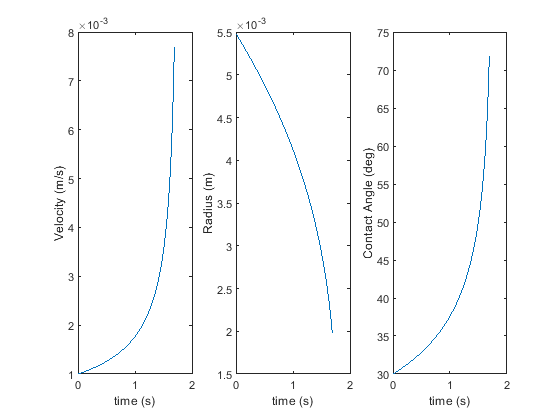

figure(1);
subplot(1,3,1);
plot(Final_t, Final_v_r,"DisplayName",'v_r');
%title("Velocity vs Time");
ylabel("Velocity (m/s)");
xlabel("time (s)");
subplot(1,3,2);
plot(Final_t, Final_r,"DisplayName",'radius');
%title("Radius vs Time");
ylabel("Radius (m)");
xlabel("time (s)");
subplot(1,3,3);
plot(Final_t, Final_theta,"DisplayName",'Contact angle');
%title("Contact Angle vs Time");
ylabel("Contact Angle (deg)");
xlabel("time (s)");

## Animating the droplet dynamics

The axes origin is (0,0,0) which is the center point of the spherical bubble.

Accordingly, the x,y,z axes have been labelled

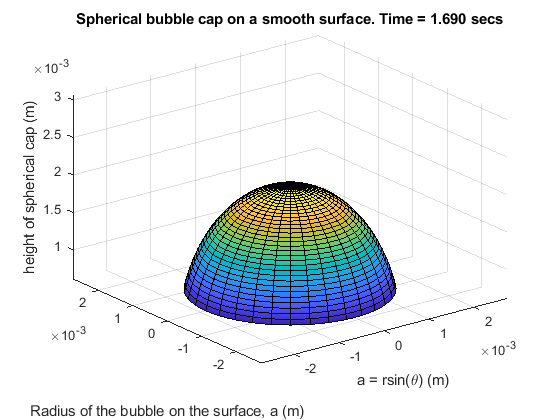

figure(2)
for i = 1: length(Final_t)
    funx = @(theta,phi) Final_r(i).*sind(theta).*cosd(phi);
    funy = @(theta,phi) Final_r(i).*sind(theta).*sind(phi);
    funz = @(theta,phi) Final_r(i).*cosd(theta);
    fsurf(funx,funy,funz,[0 Final_theta(i) -180 180])   % Surface plot
    title(sprintf('Spherical bubble cap on a smooth surface. Time = %0.3f secs', Final_t(i)));
    xlabel('a = rsin(\theta) (m)'); % Just for labelling purposes, units at x and y axis are in metres
    ylabel('Radius of the bubble on the surface, a (m)'); % ----do----
    zlabel('height of spherical cap (m)');
    xlim([-Final_r(1)*sind(Final_theta(1)) Final_r(1)*sind(Final_theta(1))]);
    ylim([-Final_r(1)*sind(Final_theta(1)) Final_r(1)*sind(Final_theta(1))]);
    zlim([Final_r(i).*cosd(Final_theta(i)) Final_r(i).*cosd(Final_theta(i)) + 4*Final_r(end).*cosd(Final_theta(end))])
    pause(0.05)
end